## Image Processing

This tutorial will showcase a variety of ways to work with and process images

### The Basics

First, read and view a sample image

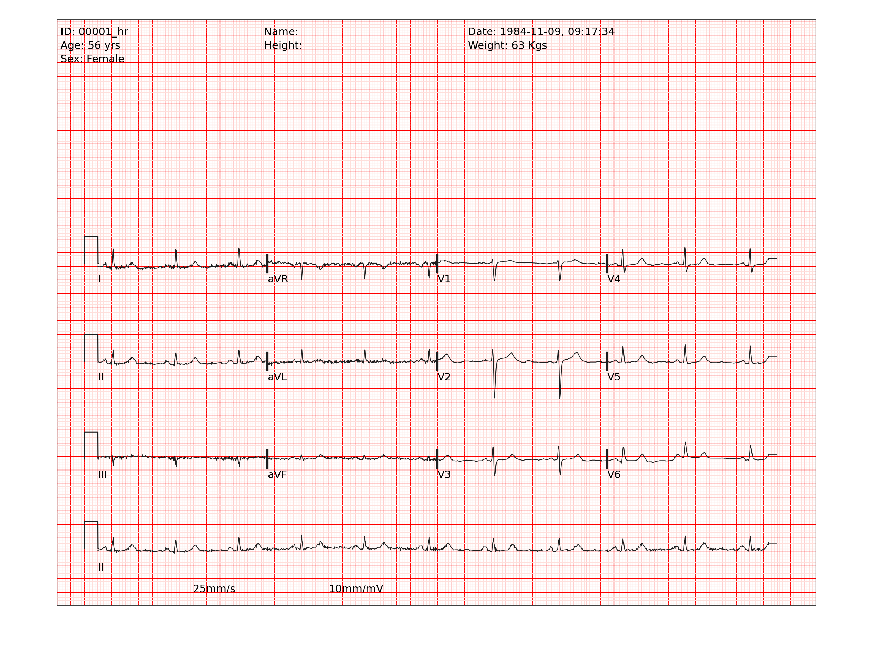

im = imread('ptb-xl\records500\00000\00001_hr-0.png');
imshow(im);

Another common task is resizing your images to make them consistent

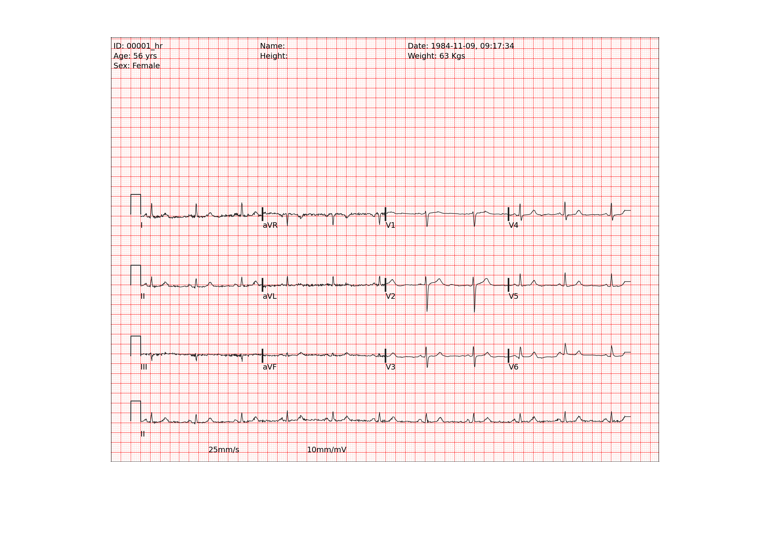

imLowRes = imresize(im, [425, 550]);
imshow(imLowRes);

You may also wish to crop the images to focus on a specific region. You can do this programmatically or interactively using the [`imcrop`](https://www.mathworks.com/help/images/ref/imcrop.html) function. This example opens a window that lets you interactively choose a region, right click and select 'Crop Image', then it crops the image and saves the coordinates of the crop you performed. 

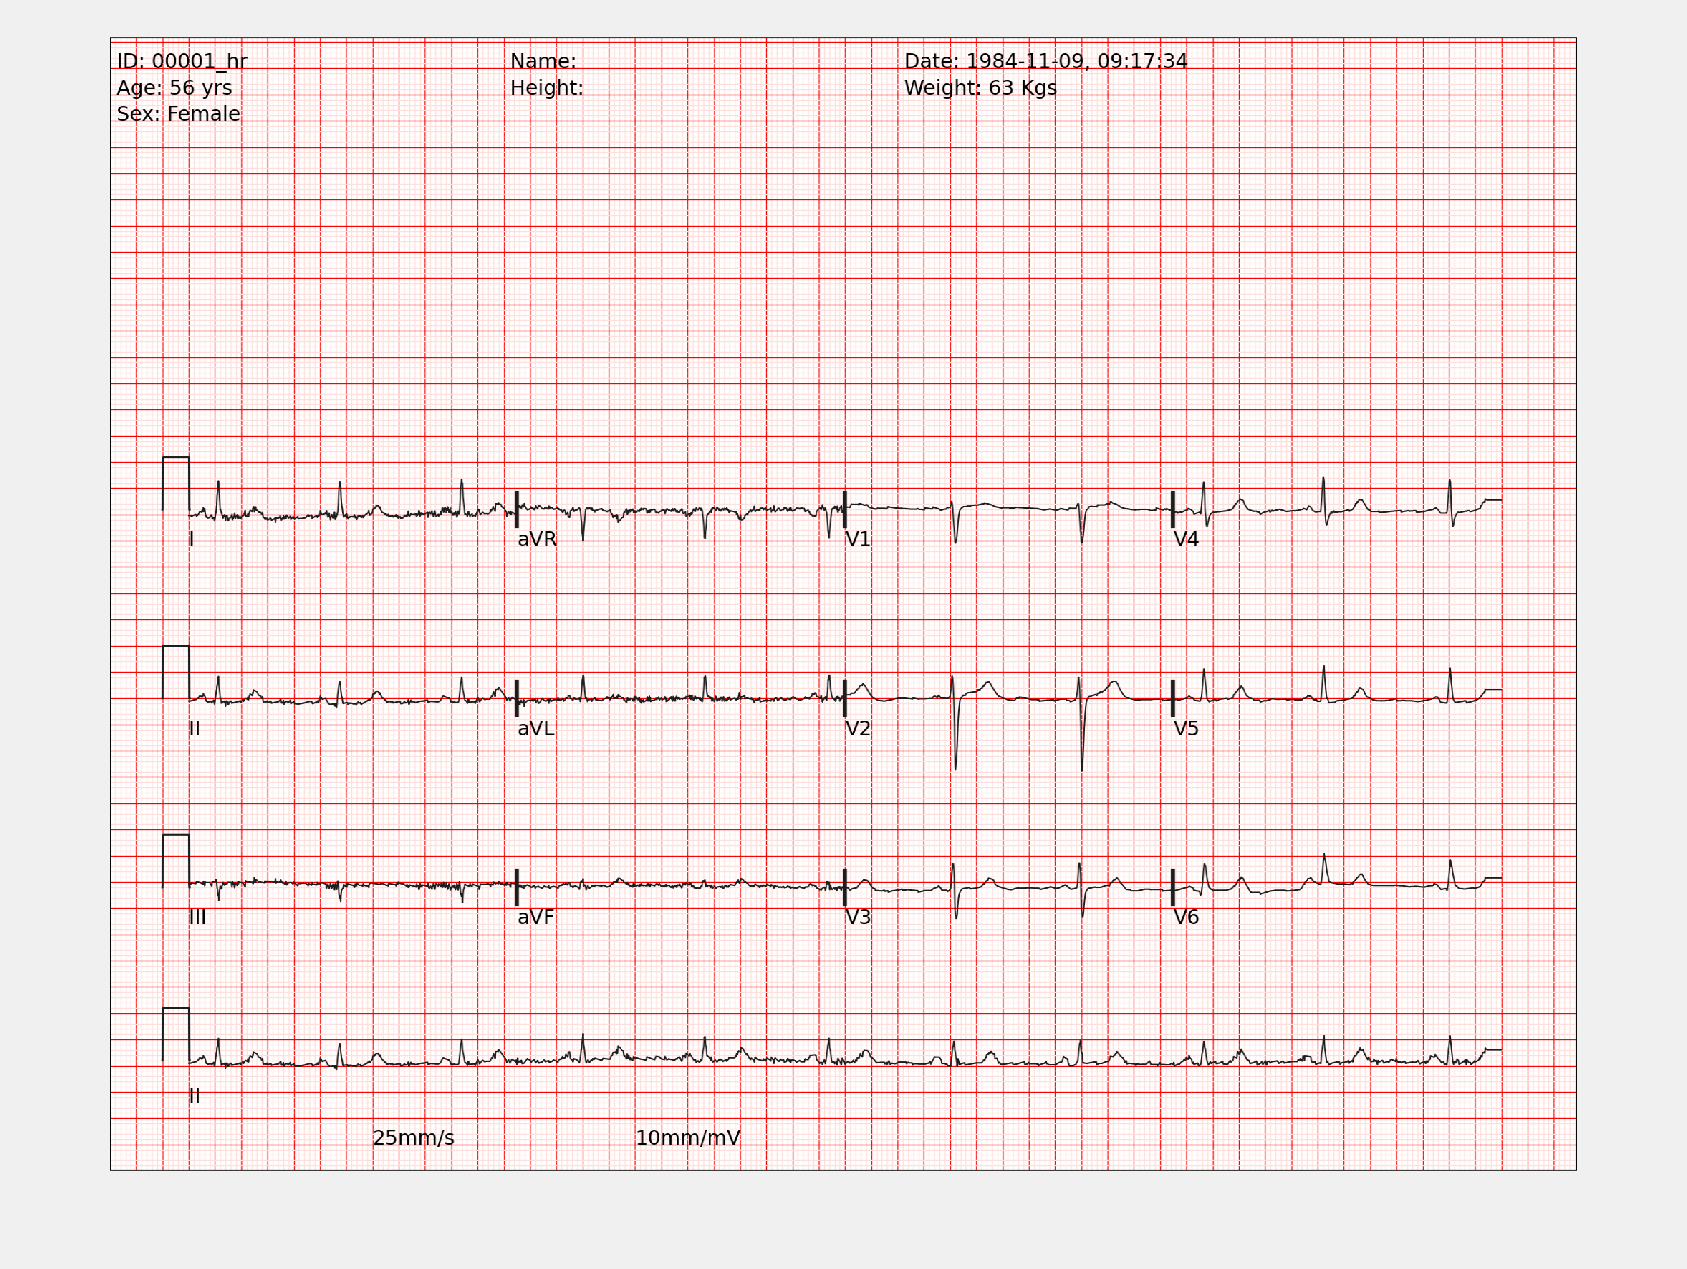

[imCropped, cropRegion] = imcrop(im);

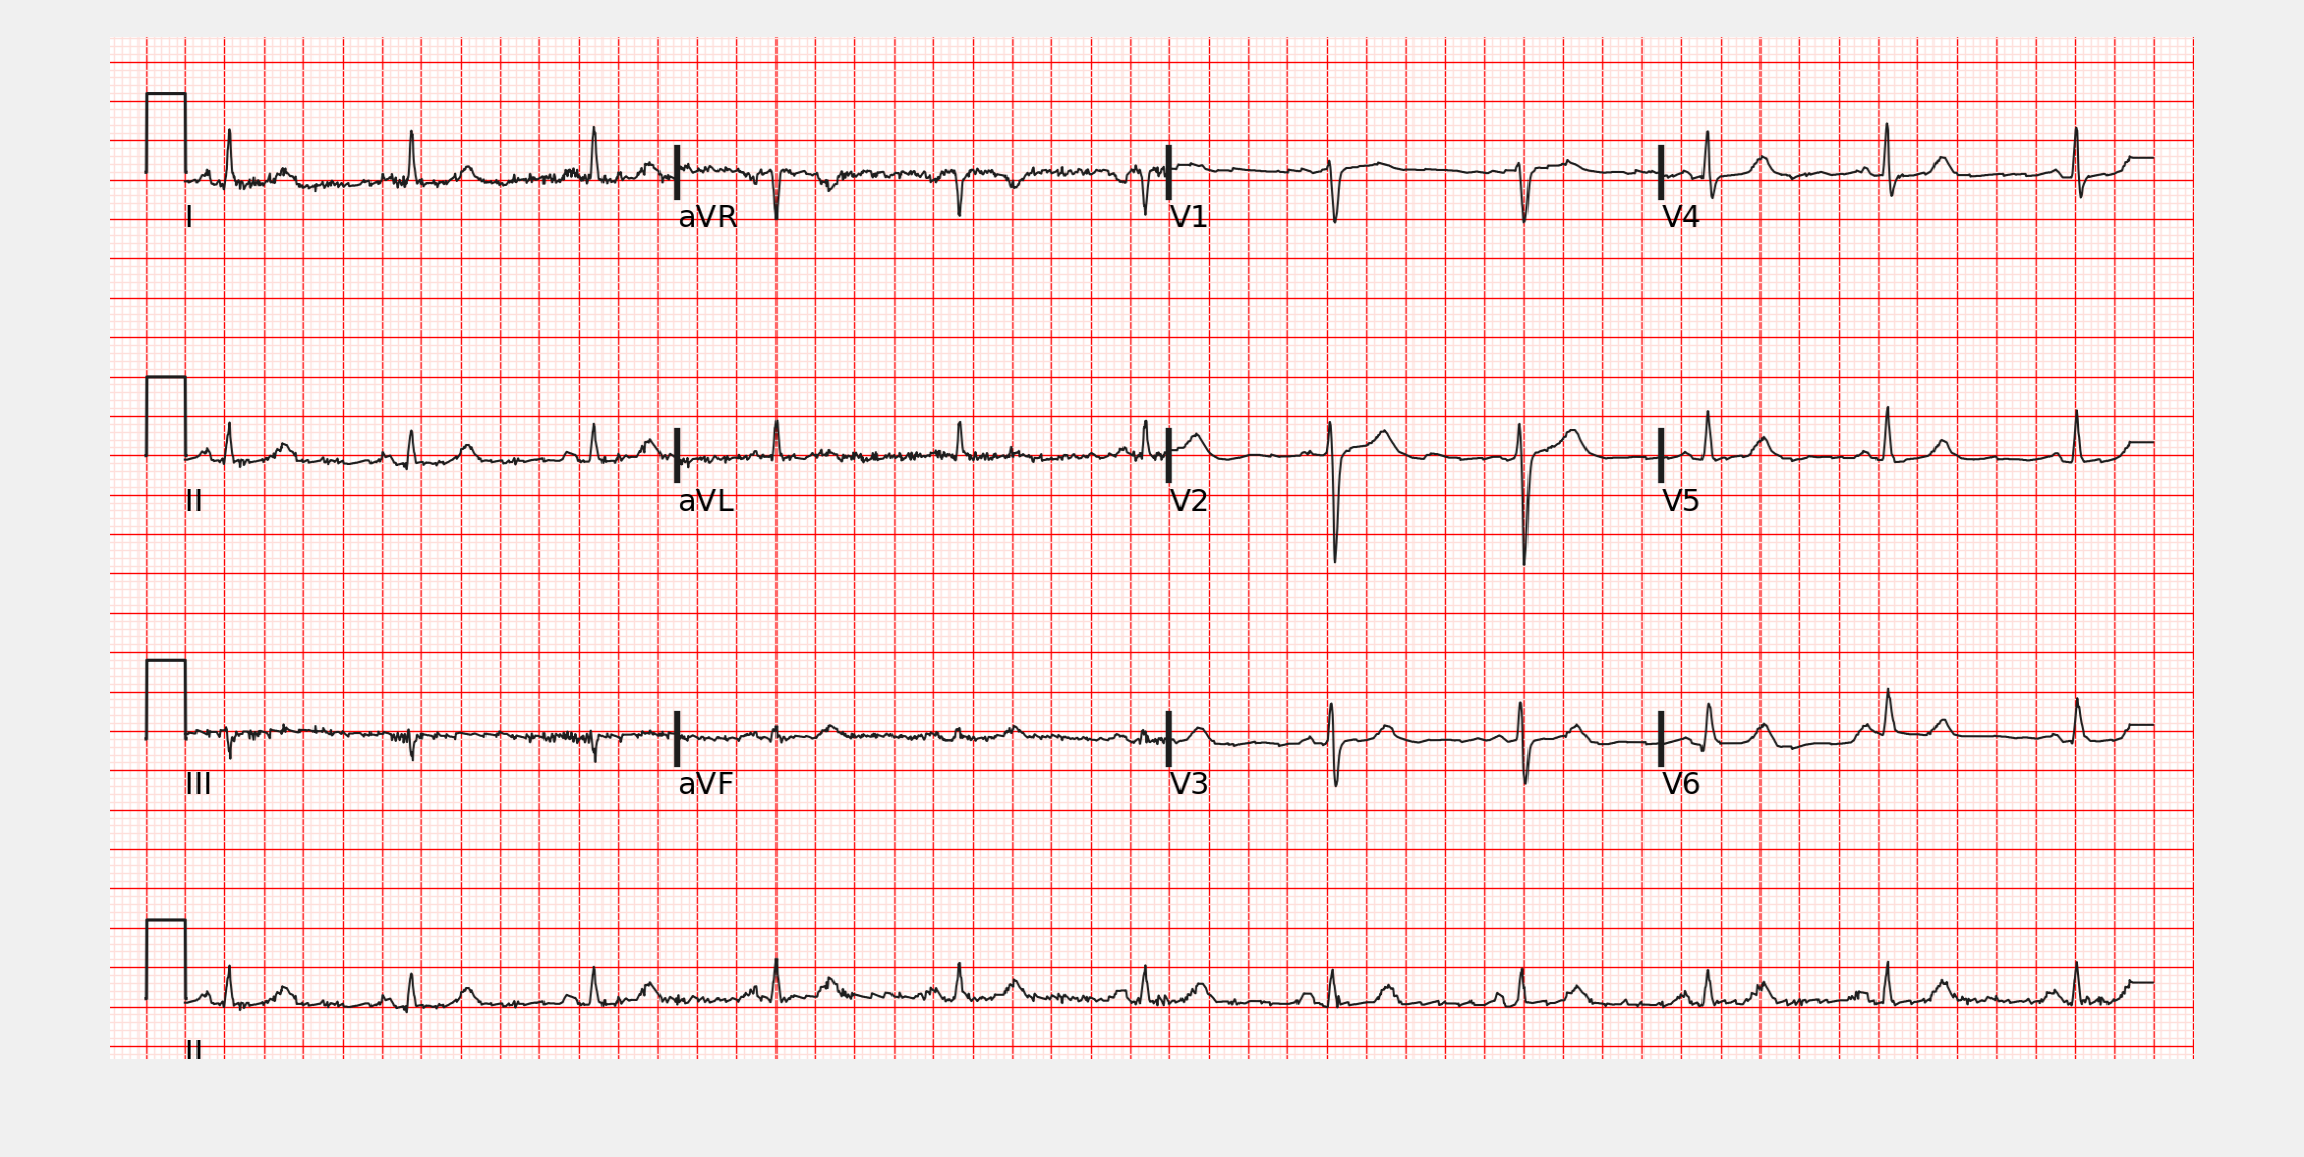

imshow(imCropped)

### Interactive Processing

You can use the [Color Thresholder app](https://www.mathworks.com/help/images/ref/colorthresholder-app.html) to perform color-based processing interactively. I used the RGB color space, but you can play around with different color spaces for different tasks.

colorThresholder

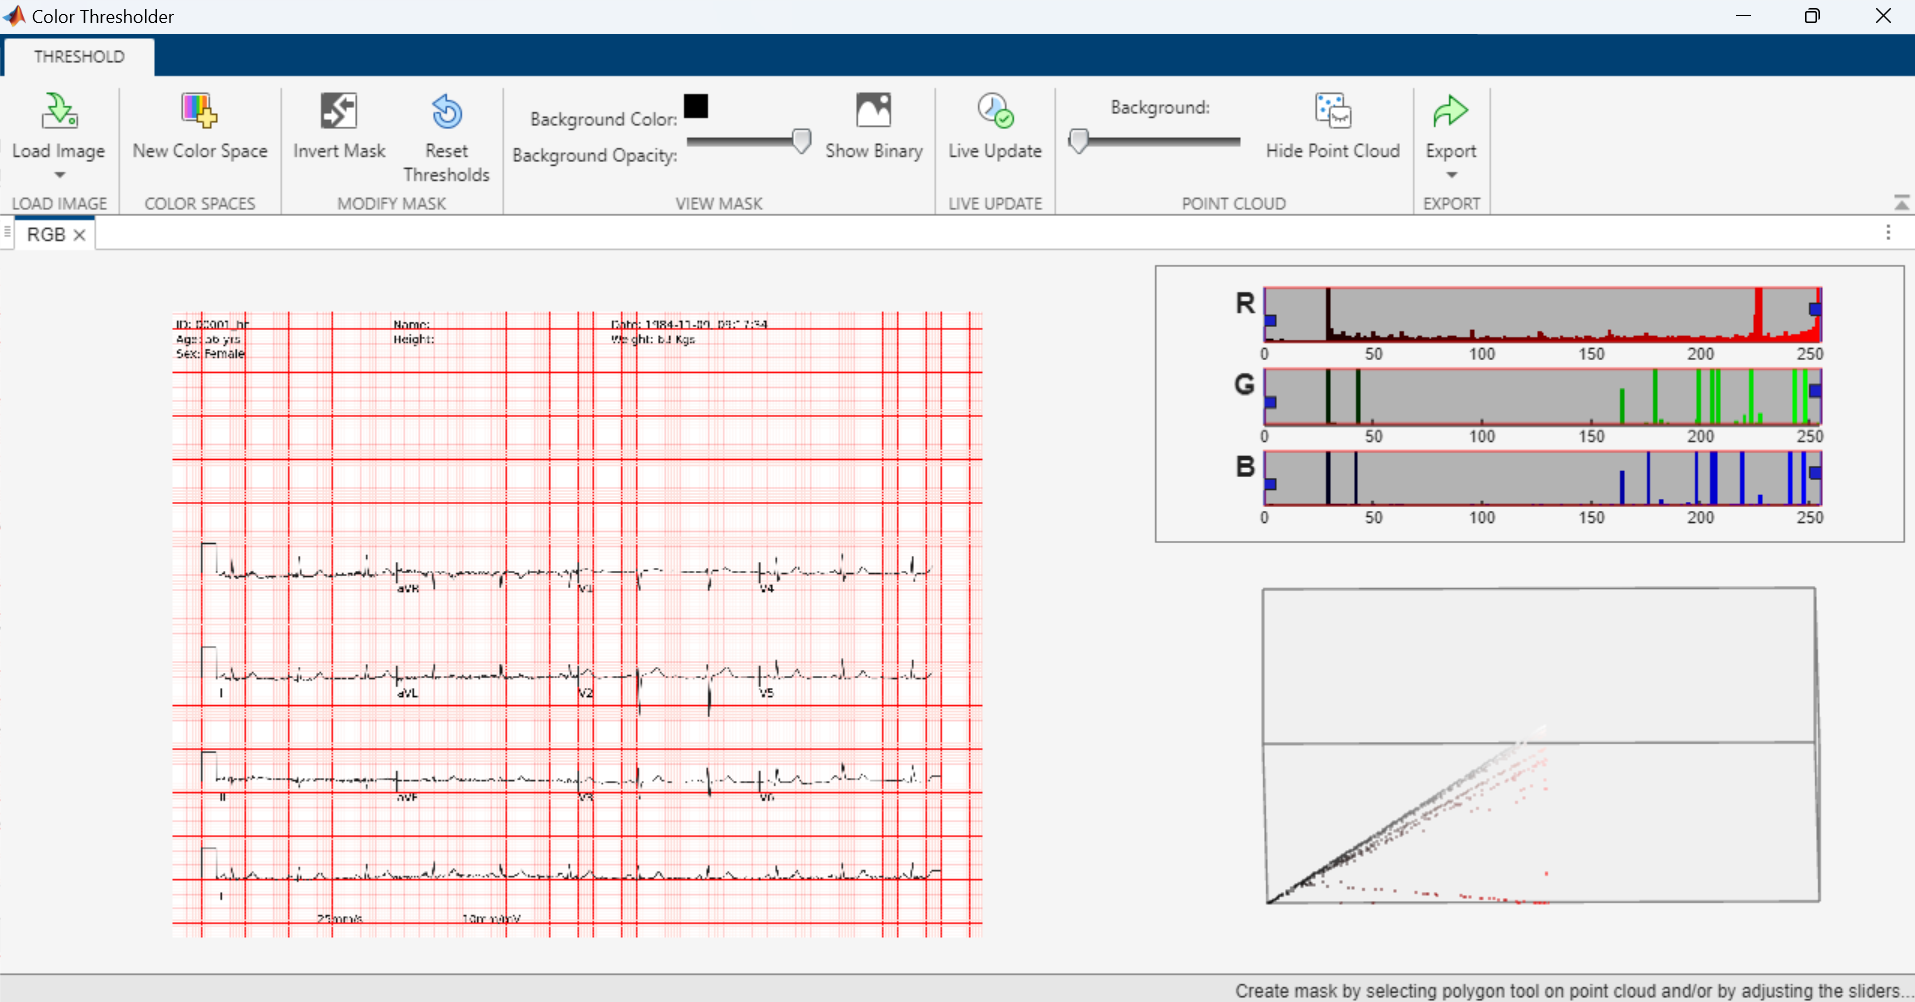

Drag the red limits down a little, then click 'Show Binary' to see the a black-and-white mask of the remaining data points in the image. This example removes the red bars of the image. 

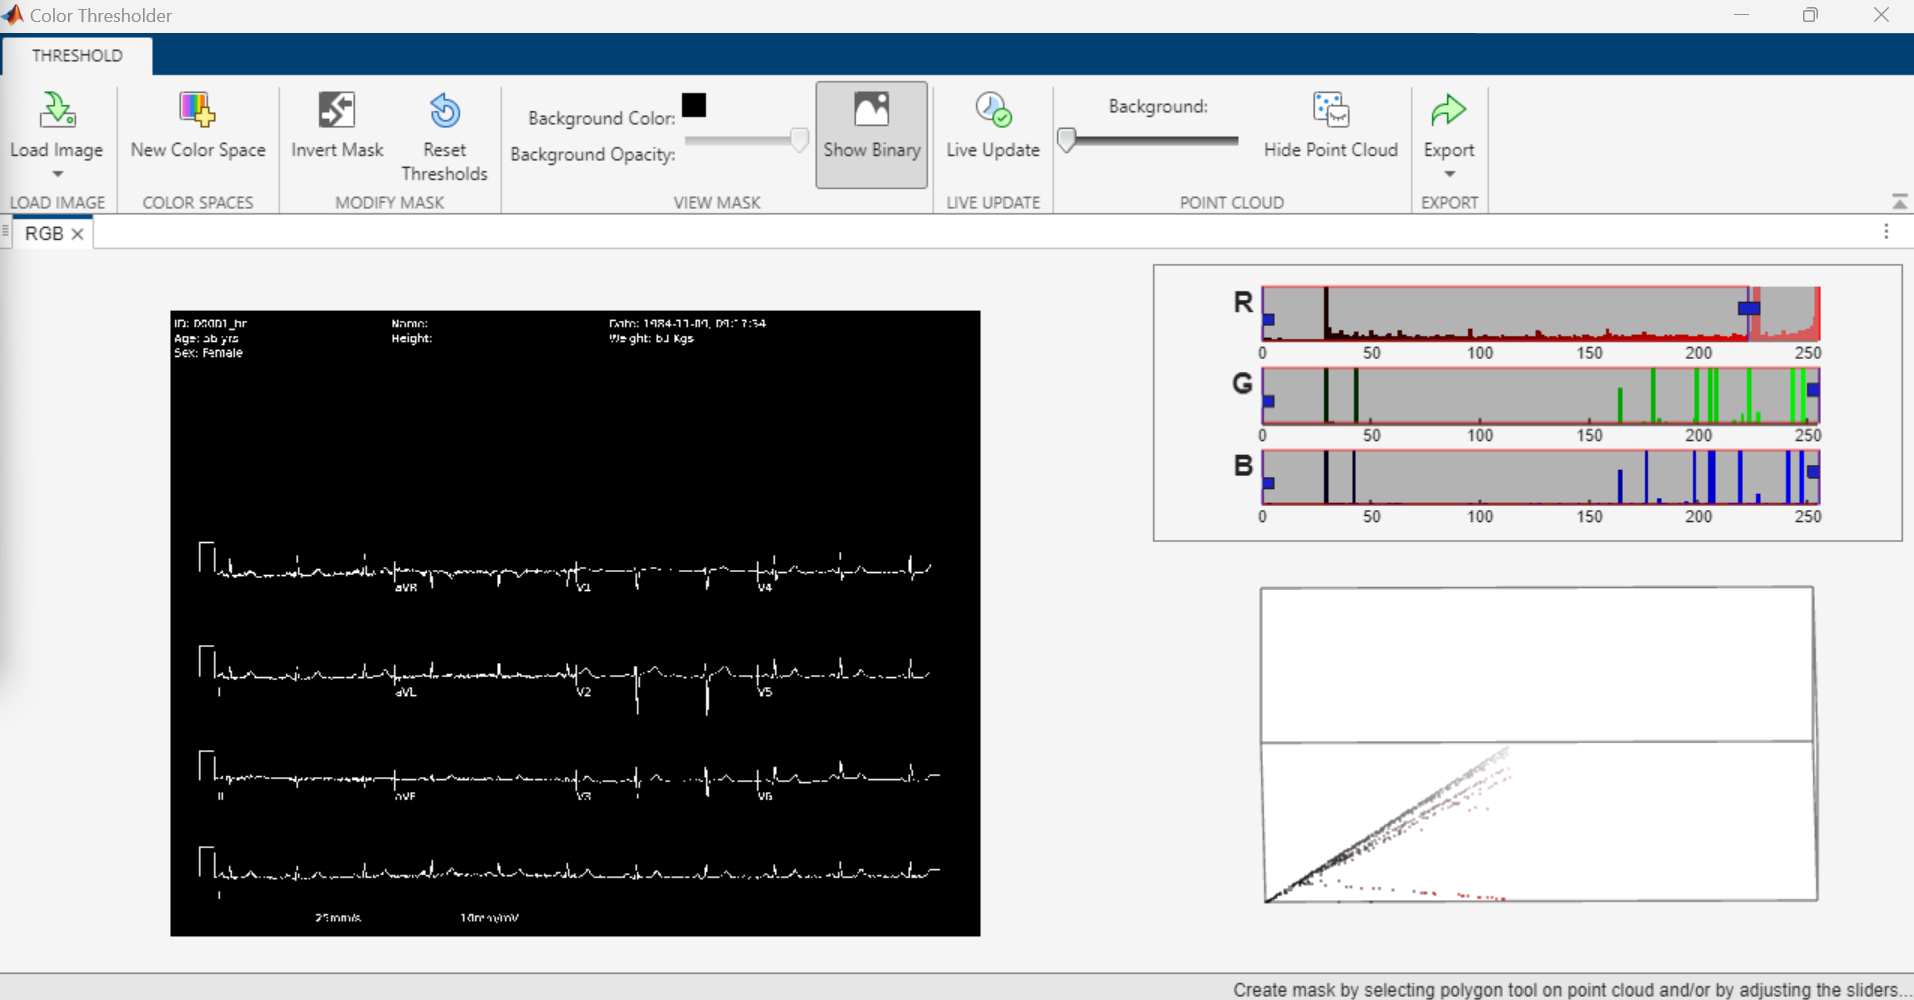

When you're happy with the mask, use the 'Export' button in the top-right corner to export the resulting images and mask, or use the 'Export Function' option to create code that can create this mask for other images.

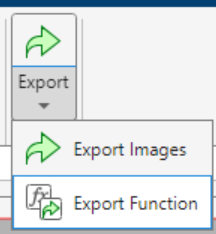

Check out this [documentation](https://www.mathworks.com/help/images/image-segmentation-using-the-color-thesholder-app.html) to learn more about how to use this application, and check out the 'APPS' tab for other interactive options for working with images.

### More Advanced - Programmatically Processing

Aside from the basics, MATLAB provides several built-in functions for manipulating images. For example, this extracts the first layer of the image and converts it to a binary image, removing the red bars, simplifying the color scheme, and enabling you to use additional processing functions. 

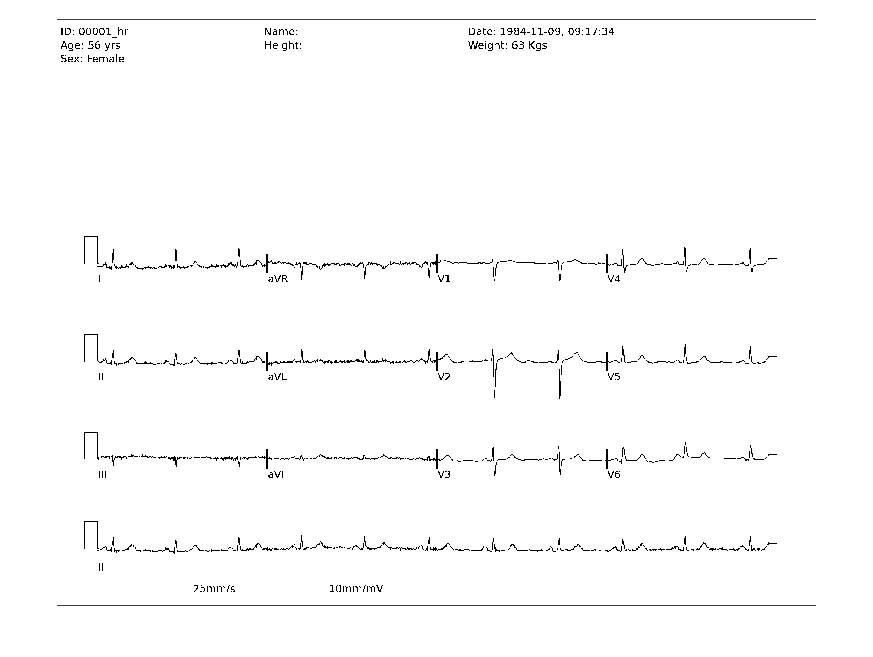

signalImg = im(:, :, 1);
signalImg = imbinarize(signalImg);
imshow(signalImg)

Then use the [`bwmorph`](https://www.mathworks.com/help/images/ref/bwmorph.html) function to apply a 'bridge' operation, which should close some of the gaps in the signals created by the red bars

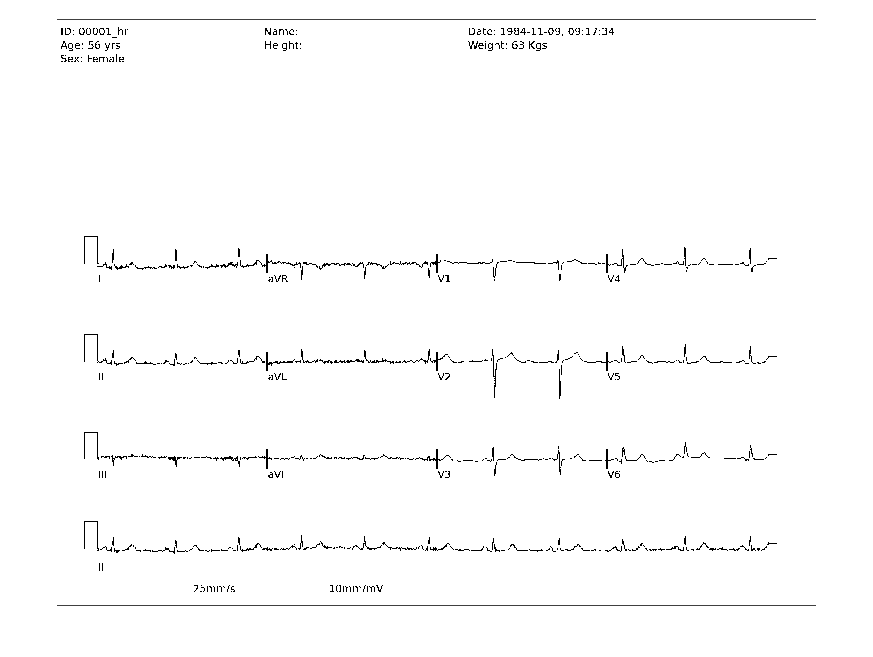

filledSignalIm = ~bwmorph(~signalImg, 'bridge', Inf);
imshow(filledSignalIm)

Last, use the bwpropfilt function to keep the 4 largest objects in the image - in this case, the signals.

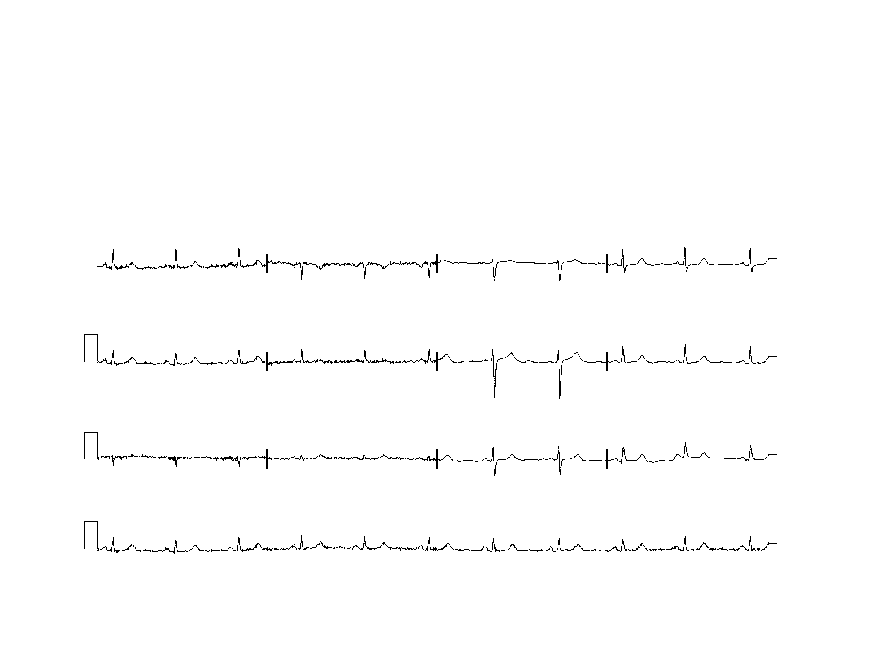

justSignals = ~bwpropfilt(~filledSignalIm,'Area',4);
imshow(justSignals)

## Other Resources

- [Deep Network Designer](https://www.mathworks.com/help/deeplearning/ref/deepnetworkdesigner-app.html): Interactively create a deep learning model with a drag-and-drop interface, use and modify pre-trained networks, or import from PyTorch and Tensorflow. 

- [Feature Detection and Extraction with Images](https://www.mathworks.com/help/vision/feature-detection-and-extraction.html)

- [Preprocess Images for Deep Learning](https://www.mathworks.com/help/deeplearning/ug/preprocess-images-for-deep-learning.html)

- [Augment Images for Deep Learning](https://www.mathworks.com/help/deeplearning/ug/image-augmentation-using-image-processing-toolbox.html)

- [Image Processing Toolbox Documentation](https://www.mathworks.com/help/images/index.html)